# Vectores De Estructuras Anidadas

Obtener un vector en el cual sus elementos son estructuras de las cuales al menos un campo de ellas es una estructura.

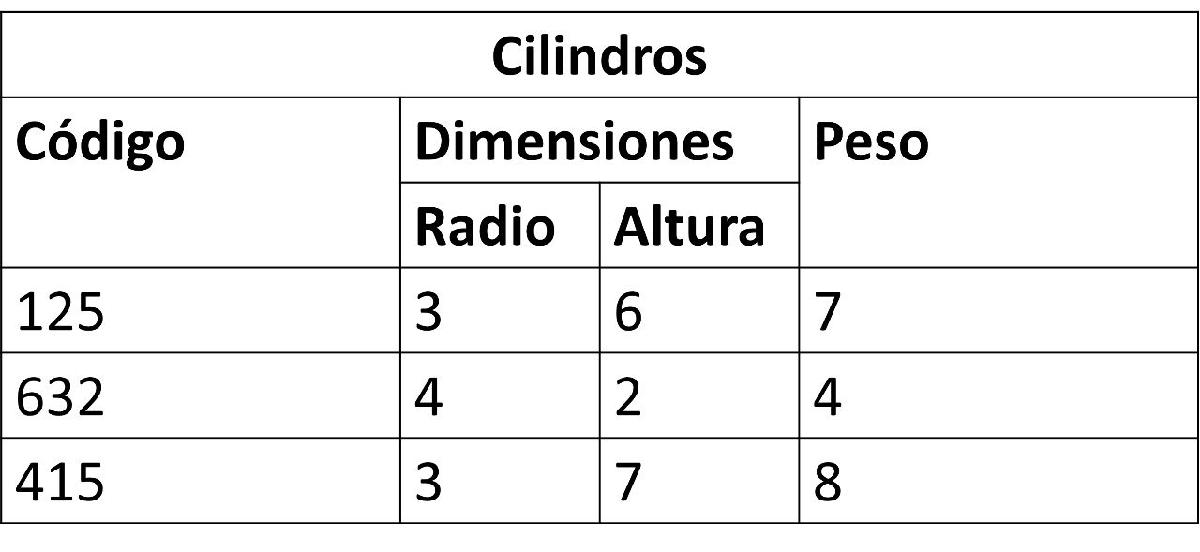

## Creracion del vector de estructuras anidadas.

cilindros(1) = struct('codigo',125,'dimensiones',struct('radio',3,'altura',6),'peso',7);
cilindros(2) = struct('codigo',632,'dimensiones',struct('radio',4,'altura',2),'peso',4);
cilindros(3) = struct('codigo',415,'dimensiones',struct('radio',3,'altura',7),'peso',8);

cilindros

cilindros = 1×3 struct array with fields:
    codigo
    dimensiones
    peso


## Acceder a los datos del vector de estructuras anidadas.

### Creacion de una funcion

Funcion para mostrar el volumen de cada cilindro del vector.

### llamar la funcion

mostrarVolumenCil(cilindros)

El cilindro de codigo 125 tiene un volumen de 169.6
El cilindro de codigo 632 tiene un volumen de 100.5
El cilindro de codigo 415 tiene un volumen de 197.9


### Creacion de la funcion

funcion para mostrar el volumen

function mostrarVolumenCil(cilindros)
    for i = 1:length(cilindros)
        vol = calcularVolumenCil(cilindros(i).dimensiones);
        fprintf("El cilindro de codigo %d tiene un volumen de %.1f\n",cilindros(i).codigo,vol);
    end
end

funcion para calcular el volumen

pi * rad^2 * altura

function cvol = calcularVolumenCil(dimensiones)
    cvol = pi * dimensiones.radio^2 * dimensiones.altura;
end